%% 1. Load Data Hardcoded from Figure
% Opens the figure invisibly to extract data
% (Ignores the 'proplistener' warnings automatically)
fig = openfig('sim_traj.fig', 'invisible');
ax = gca;
a = get(ax, 'Children');

% --- HARDCODED SELECTION ---
obj_1 = a(1); % Line 1
obj_2 = a(2); % Line 2 

%% 2. Process Line 1
x_raw_1 = obj_1.XData;
y_raw_1 = obj_1.YData;

% Filter Window (updated to your 0-50000 logic)
idx_1 = (x_raw_1 >= 120) & (x_raw_1 <= 50000);

% Extract Y Data
y_1 = y_raw_1(idx_1)';

% --- RECONSTRUCT TIME VECTOR (Start at 0) ---
t_temp_1 = x_raw_1(idx_1);      
Ts_1 = mean(diff(t_temp_1));    
N_1 = length(y_1);              
duration_1 = (N_1 - 1) * Ts_1;  

% Create new time vector: 0 to duration
t_1 = linspace(0, duration_1, N_1)';

fprintf('Line 1 processed: %d points. Ts = %.4f s. Time reset to [0 - %.2f]s\n', N_1, Ts_1, duration_1);

Line 1 processed: 96001 points. Ts = 0.0050 s. Time reset to [0 - 480.00]s



%% 3. Process Line 2
x_raw_2 = obj_2.XData;
y_raw_2 = obj_2.YData;

% Filter Window
idx_2 = (x_raw_2 >= 120) & (x_raw_2 <= 50000);

% Extract Y Data
y_2 = y_raw_2(idx_2)';

% --- RECONSTRUCT TIME VECTOR (Start at 0) ---
t_temp_2 = x_raw_2(idx_2);
Ts_2 = mean(diff(t_temp_2));
N_2 = length(y_2);
duration_2 = (N_2 - 1) * Ts_2;

% Create new time vector: 0 to duration
t_2 = linspace(0, duration_2, N_2)';

fprintf('Line 2 processed: %d points. Ts = %.4f s. Time reset to [0 - %.2f]s\n', N_2, Ts_2, duration_2);

Line 2 processed: 96001 points. Ts = 0.0050 s. Time reset to [0 - 480.00]s


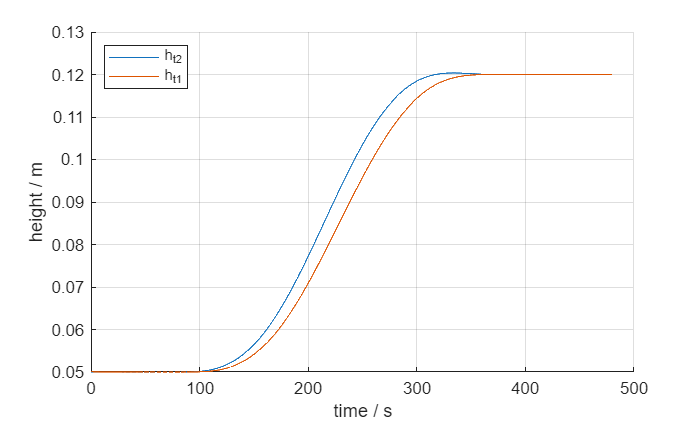


% Close the source figure
close(fig);

%% 4. Visualize and Export
f_new = figure; 
hold on; grid on;

plot(t_1, y_1, 'DisplayName', 'h_{t2}');
plot(t_2, y_2, 'DisplayName', 'h_{t1}');

xlabel('time / s');
ylabel('height / m');

% Legend in Top-Left
legend('show', 'Location', 'northwest');

% --- EXPORT TO PDF ---
pdf_filename = 'wt_sim_traj.pdf';

% Check for modern MATLAB export function (R2020a+)
if exist('exportgraphics', 'file')
    exportgraphics(f_new, pdf_filename, 'ContentType', 'vector');
else
    % Fallback for older MATLAB versions
    print(f_new, pdf_filename, '-dpdf', '-bestfit');
end

fprintf('Figure saved as: %s\n', pdf_filename);

Figure saved as: wt_sim_traj.pdf
